# Shadow Bot Calculations

**The governing equations are : **

Let the Thrust supplied by the EDF be T,

and the Weight off the bot be W, then

for **No Sliding**,


$$\mathit{\mathbf{T}}\ge \frac{\mathit{\mathbf{W}}}{\mu }$$


and for **No Toppling**,


$$\mathit{\mathbf{W}}\le \mathit{\mathbf{T}}\ast \frac{\mathit{\mathbf{x}}}{\mathit{\mathbf{c}}}$$


where,

x is the point of application of thrust from the rear wheel of the bot,

c is the clearance of the bot with the ground.

For the bot to move ,

Motor torque,**M** required is ,


$$\mathit{\mathbf{M}}\ge \frac{\mathit{\mathbf{W}}\ast \mathit{\mathbf{R}}}{2}$$


where,

R = radius of the wheel.

And also the bot should satisfy these conditions while running,


$$\mathit{\mathbf{T}}\ge \mathit{\mathbf{W}}\ast \frac{\mathit{\mathbf{c}}}{\mathit{\mathbf{x}}}-\frac{\mathit{\mathbf{M}}}{\mathit{\mathbf{x}}}$$



$$\mathit{\mathbf{M}}\ge \text{ }\frac{\left(\mu \frac{\mathit{\mathbf{T}}}{2}-\frac{\mu \mathit{\mathbf{W}}}{4}+{\mathit{\mathbf{m}}}_0 \frac{\mathit{\mathbf{W}}}{\left(\frac{\mathit{\mathbf{W}}}{\mathit{\mathbf{g}}}+2{\mathit{\mathbf{m}}}_0 \right)}\right)}{\left(\frac{{\mathit{\mathbf{m}}}_0 }{\left(\mathit{\mathbf{R}}{\mathit{\mathbf{m}}}_0 +\frac{\mathit{\mathbf{W}}}{\mathit{\mathbf{g}}}\right)}-\frac{\mu }{2\mathit{\mathbf{L}}}\right)}$$


which has to ensured.

**Thrust vs W_max of the bot calculation for different Thrust_distance(x)/clearance of bot ratios keeping other parameters fixed :**

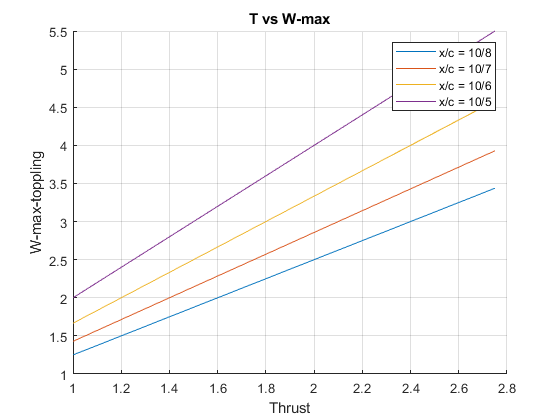

% Thrust vs W_max of the bot calculation for different
% Thrust_distance(x)/clearance of bot ratios keeping 
% other parameters fixed
x = table2array(TvsM(13:27,2));
y = table2array(TvsM(13:27,10));
x1 = table2array(TvsM(28:42,2));
y1 = table2array(TvsM(28:42,10));
x2 = table2array(TvsM(43:57,2));
y2 = table2array(TvsM(43:57,10));
x3 = table2array(TvsM(58:72,2));
y3 = table2array(TvsM(58:72,10));
figure;
hold on;
xlabel('Thrust');
ylabel('W-max-toppling');
title('T vs W-max');
plot(x,y,x1,y1,x2,y2,x3,y3);
legend('x/c = 10/8','x/c = 10/7','x/c = 10/6','x/c = 10/5');
grid on;
hold off;

**Motor Torque vs Thrust for the same above conditions :**

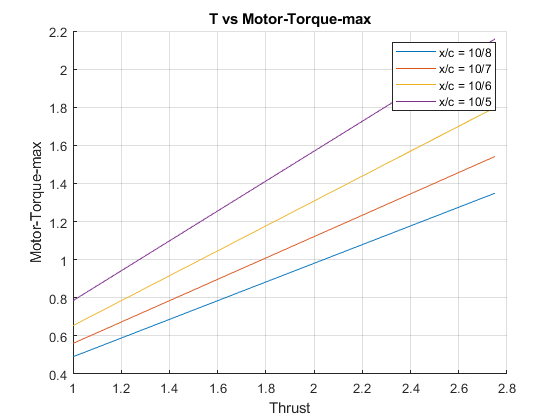

% Motor Torque vs Thrust for the same above conditions 
z = table2array(TvsM(13:27,12));
z1 = table2array(TvsM(28:42,12));
z2 = table2array(TvsM(43:57,12));
z3 = table2array(TvsM(58:72,12));
figure;
hold on;
xlabel('Thrust');
ylabel('Motor-Torque-max');
title('T vs Motor-Torque-max');
plot(x,z,x1,z1,x2,z2,x3,z3);
legend('x/c = 10/8','x/c = 10/7','x/c = 10/6','x/c = 10/5');
grid on;
hold off;

**The Min Motor Torque** ,${\mathit{\mathbf{M}}}_{\mathbf{min}}$ $\ge \frac{{\mathit{\mathbf{W}}}_{\mathbf{min}} \ast \mathit{\mathbf{R}}}{2}$

**and **$W_{\min }$** = **$\mu \ast \mathit{\mathbf{T}}$** and hence depends on **$\mu$** and T only. It does not depend on other parameters.**

## **Front Wheel Motor Torque:**

Calculations for the minimum motor torque required to actuate the front links :

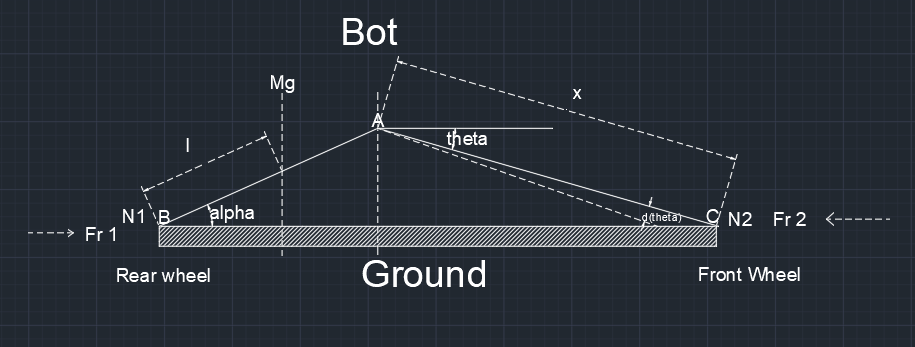

Analysing the bot using the method of **virtual work** to obtain the min Motor torque required we get,

Le the distance of the center of mass of the bot from the rear wheels be $l$,

the length of the front links be $x$.

Let's say that the motor produces a torque, $M_f$ to actuate the front wheels,

the **Work done** by the **motor** to rotate the link by an angle $d\theta$ = $M_f *d\theta$

To find Work done by gravity :

Using sine rule in the triangle ABC we get,


$$\frac{\sin \left(\theta \right)}{L}=\frac{\sin \left(\alpha \right)}{x}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\to \left(1\right)$$
 

let the height of the centre of mass of the bot from the ground be $h$,


$$h=l*\mathrm{sin}\left(\alpha \right)$$


but from (1) we get $L*\sin \left(\alpha \right)=x*\sin \left(\theta \right)$

but $L=l+y$ , where

$l=$distance of COM from the back link along the back link

Removing the unknown variable y and relating l and L with the height we get ,

$h=\frac{\left(l*\mathrm{sin}\left(\theta \right)*x\right)}{L}$ and therefore, 

so $\textrm{dh}=\frac{l*d\theta *\mathrm{cos}\left(\theta \right)*x}{L}$

**Work done** by **gravity** during this time = - $M*g*x*\mathrm{cos}\left(\theta \right)*d\theta$ ,

the minus sign indicates that the gravity does negative work.

**Work done** by the **normal reactions** $N_{1\;} ,N_{2\;} =0$ , since there is not net displacement in the vertical direction.

But , frictional force ${\mathrm{Fr}}_2 \;$ does some work 

let the distance of the front wheel from the point of connection of the front links be $y$ then,


$$\begin{array}{l}
y=x*\mathrm{cos}\left(\theta \right)\;\\
\mathrm{dy}=-x*\mathrm{sin}\left(\theta \right)*d\theta 
\end{array}$$


**Work done** by **frictional force** ${\textrm{Fr}}_2$ = ${\mathrm{Fr}}_2 \;*x*\mathrm{sin}\left(\theta \right)*d\theta$

Now using work energy theorem we get ,

Work done by net forces , $W_{\mathrm{net}} =\Delta \;{\mathrm{KE}}_{\mathrm{system}}$ but since the system is at rest , 

$\Delta \;{\textrm{KE}}_{\textrm{system}}$ = 0 

and we get ,

- $M*g*x*\mathrm{cos}\left(\theta \right)*d\theta$ + (${\textrm{Fr}}_2 \;*x*\sin \left(\theta \right)*d\theta \;$) + $M_f *d\theta$ = $0$

$M_f$ = $M*g*x*\cos \left(\theta \right)$ - ${\textrm{Fr}}_2 \;*x*\sin \left(\theta \right)$

and at $\theta =0^o \;$we get ,

$M_f$ = $\frac{M*g*x*l}{L}$ 

which is the minimum Motor Torque required by the front wheels to be actuated.

**Wheel Design :**

Euler characteristic ($\left.\chi \right)$ of Wheel (Disc) is 1.

But,

$\chi =V-E+F$ where,

V is the number of vertices,

E is the number of edges,

F is the number of faces.

Let the disc contain P number of Pentagons,

H number of Hexagons,

then,


$$V=\;\frac{5*P+6*H}{3}$$



$$E=\frac{5*P+6*H}{2}$$



$$F=P+H$$


Substituting these values we get,


$$P=6$$


But we need to find the number of Hexagons,

The number of Hexagons can be arbitrary to fill the remaining space,

Here I needded 5 hexagons to cover the fill the disk.

So for our case,


$$H=5\ldotp$$